tic();
imds = imageDatastore('/media/titan/Storage 1/101_ObjectCategories', 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

tbl = countEachLabel(imds)

tbl = 101×2 table
       Label        Count
    ____________    _____

    Faces            435 
    Faces_easy       435 
    Leopards         200 
    Motorbikes       798 
    accordion         55 
    airplanes        800 
    anchor            42 
    ant               42 
    barrel            47 
    bass              54 
    beaver            46 
    binocular         33 
    bonsai           128 
    brain             98 
    brontosaurus      43 
    buddha            85 



minSetCount = min(tbl{:,2}); % determine the smallest amount of images in a category

% Use splitEachLabel method to trim the set.
imds1 = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 101×2 table
       Label        Count
    ____________    _____

    Faces            435 
    Faces_easy       435 
    Leopards         200 
    Motorbikes       798 
    accordion         55 
    airplanes        800 
    anchor            42 
    ant               42 
    barrel            47 
    bass              54 
    beaver            46 
    binocular         33 
    bonsai           128 
    brain             98 
    brontosaurus      43 
    buddha            85 


imds2 = splitEachLabel(imds, minSetCount, 'randomize');


% Load pre-trained AlexNet
net1 = alexnet()

net1 =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]



% View the CNN architecture
net1.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10 

% Load pre-trained VGG19
net2 = vgg19()

net2 =   SeriesNetwork with properties:

    Layers: [47×1 nnet.cnn.layer.Layer]



net2.Layers

ans =   47x1 Layer array with layers:

     1   'input'     Image Input             224x224x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   

% Number of class names for ImageNet classification task
numel(net1.Layers(end).ClassNames)

ans = 1000


% Set the ImageDatastore ReadFcn
imds1.ReadFcn = @(filename)readAndPreprocessImage1(filename);

[trainingSet1, testSet1] = splitEachLabel(imds1, .6, 'randomize');

% Number of class names for ImageNet classification task
numel(net2.Layers(end).ClassNames)

ans = 1000


% Set the ImageDatastore ReadFcn
imds2.ReadFcn = @(filename)readAndPreprocessImage2(filename);

[trainingSet2, testSet2] = splitEachLabel(imds2, .6, 'randomize');

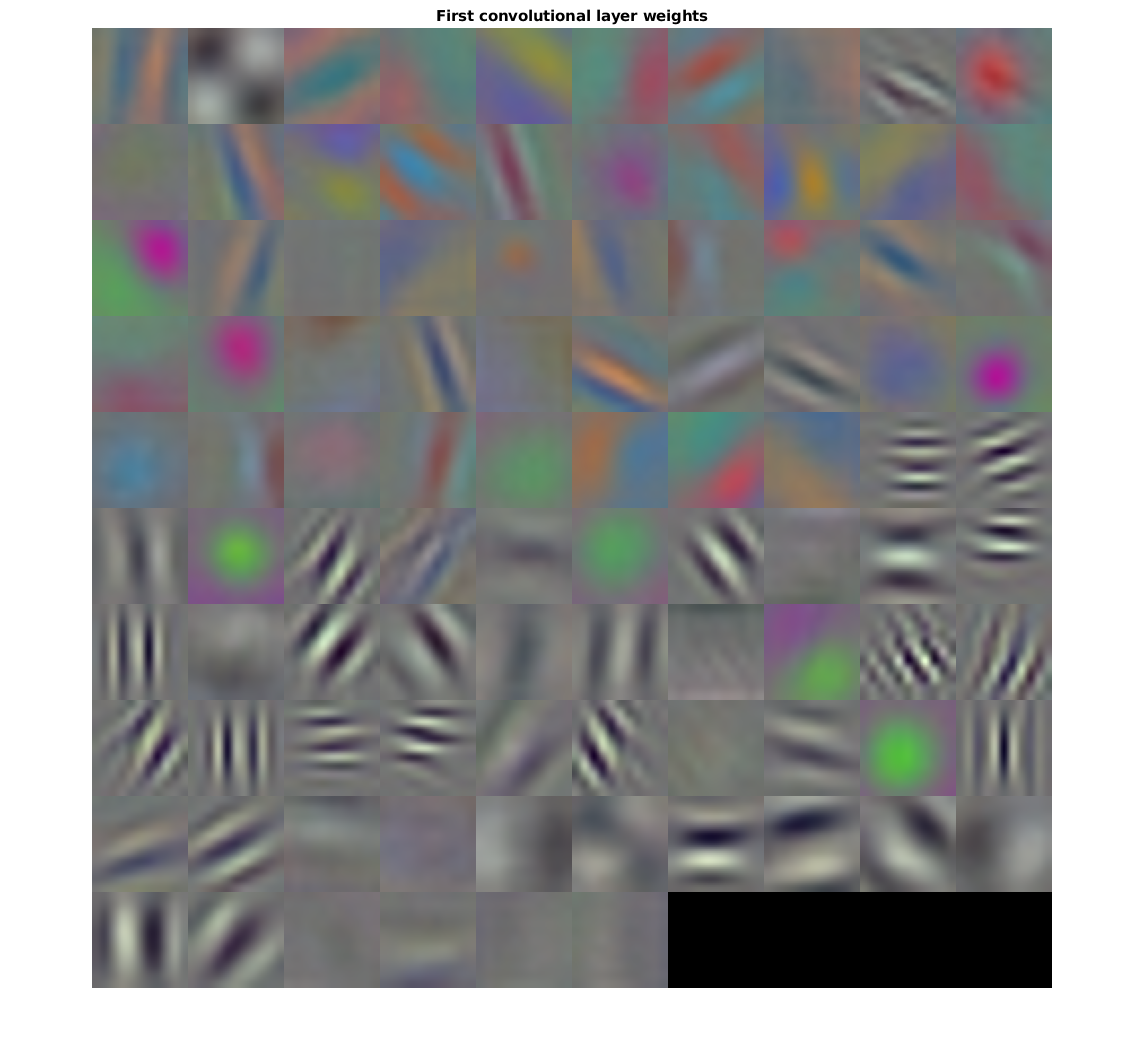

% Get the network weights for the second convolutional layer
w1 = net1.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5);

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)
title('First convolutional layer weights')

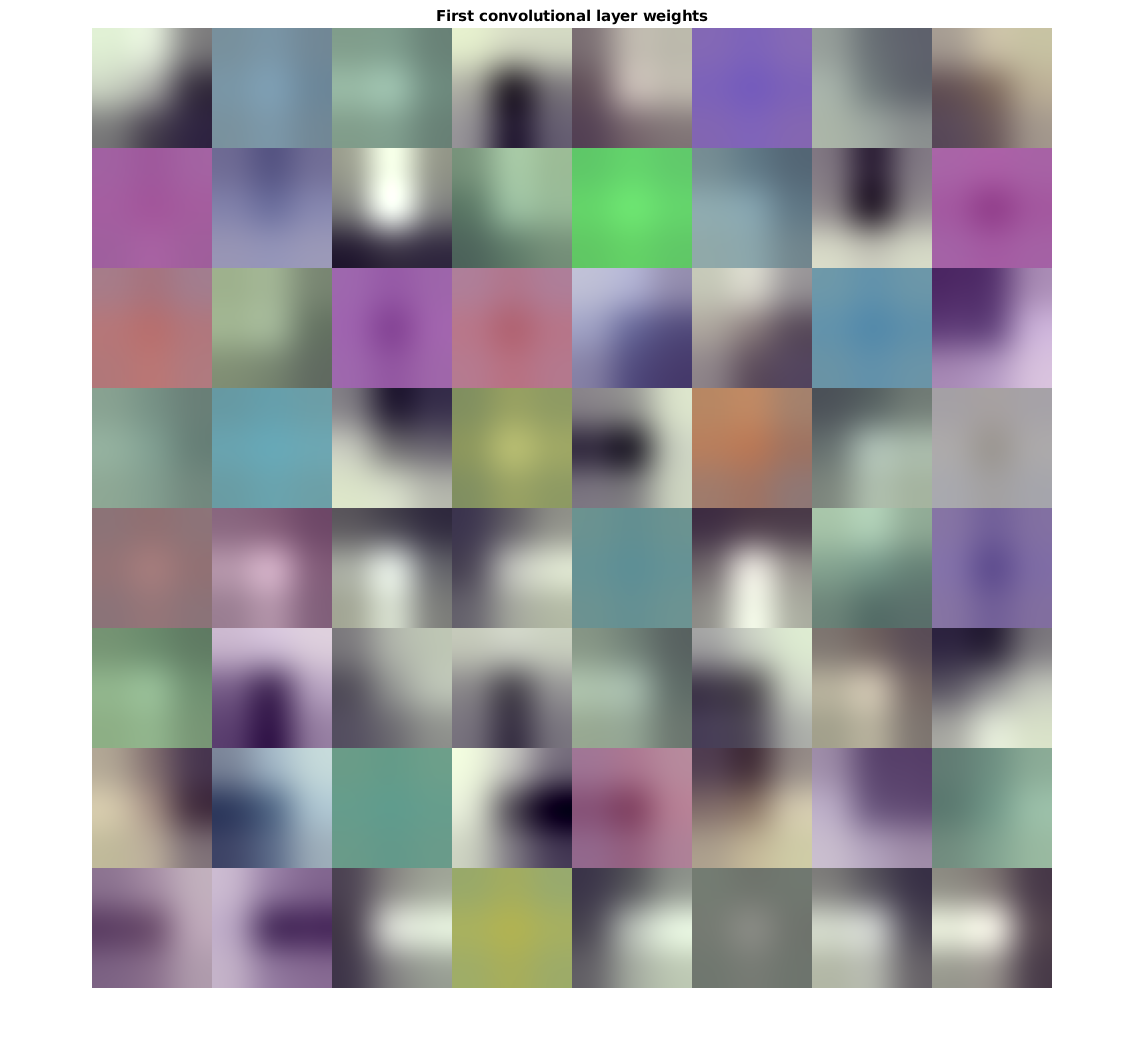

% Get the network weights for the second convolutional layer
w2 = net2.Layers(2).Weights;

% Scale and resize the weights for visualization
w2 = mat2gray(w2);
w2 = imresize(w2,5);

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w2)
title('First convolutional layer weights')

featureLayer = 'fc7';
trainingFeatures1 = activations(net1, trainingSet1, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows',...
    'ExecutionEnvironment','gpu');
trainingFeatures1

trainingFeatures1 = 1919×4096 single matrix
   -2.9007   -0.8410   -6.5257   -3.3703   -1.4939   -3.4555   -5.6935   -7.3358   -2.1571   -5.8881   -1.7250   -3.5510   -4.9582   -1.1766   -2.1526    0.9936   -5.1462    1.2710   -2.4165   -3.8530   -4.9769   -1.7374   -9.4810   -7.8040   -1.9099   -2.3878   -5.1380  -12.8595   -4.8770   -5.5896   -7.0998   -1.2066   -4.1035   -2.3248   -3.9963   -7.5287   -7.6791    7.0926   -3.7316    4.9155    1.0661   -7.6156    2.6286   -4.3639  -11.1913    3.4838   -6.2637    6.7499   -1.1524   -0.7123
   -2.1537    1.6987   -5.9463   -2.0774    0.8174   -2.4790   -3.1402   -3.3736   -0.0638   -6.8109   -0.6033   -5.0713   -4.7300   -7.3514   -1.2877   -5.3554   -2.4185   -3.6799    0.9035   -5.2020   -6.3232    3.0162   -1.5672   -4.3429   -6.0676   -5.5929   -7.1234  -10.1730  -10.3335    1.1613   -6.6186    3.5417   -3.3732    0.6360   -4.7313   -5.1851   -5.7521   -2.4394   -5.0604   -5.8031   -1.6442   -3.6913   -1.7920  -10.3000   -4.7154    0

featureLayer = 'fc7';
trainingFeatures2 = activations(net2, trainingSet2, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows',...
    'ExecutionEnvironment','gpu');
trainingFeatures2

trainingFeatures2 = 1919×4096 single matrix
   -4.8099   -4.0393   -2.7055   -5.9856    0.3142   -2.8551   -6.6709   -3.0492    2.2208   -2.8178   -1.4708   -4.9220    5.7406    5.2157  -10.6318   -3.6307   -5.2549   -7.2178   -1.2780   -3.4770   -6.0508   -3.1979   -3.1172   -7.1031   -2.0096    1.9464   -2.0986   -8.3598   -6.9946  -10.5243   -1.5709   -2.5674   -8.5919   -0.7331   -0.8019    0.1688    0.6169   -6.2727   -2.9378   -2.1563   -5.6389   -0.5615   -2.4445   -3.9512  -10.7003   -1.1060   -3.7468   -4.6028   -1.4411   -3.6931
   -1.4071   -1.1328   -0.5741   -2.5552   -1.2203   -0.3876   -3.4013   -2.9006    1.7678    0.2689   -1.7407   -3.0993    1.8790    4.7766   -3.3040   -1.6113   -2.9576   -4.8983    0.2427   -1.6234    0.9945   -1.6733   -2.1697   -3.7430   -0.1655   -0.1104   -4.8816   -6.4487   -2.9549   -6.5402    0.0303   -1.9030   -4.6300   -0.0670    0.2437   -1.4110    1.5369   -5.6753   -0.4515   -0.5606   -0.7114   -2.2008   -0.9894   -3.2078   -4.3297   -1

fusionFeatures = trainingFeatures1 + trainingFeatures2;
fusionFeatures

fusionFeatures = 1919×4096 single matrix
   -7.7105   -4.8803   -9.2312   -9.3559   -1.1797   -6.3106  -12.3644  -10.3849    0.0637   -8.7059   -3.1958   -8.4731    0.7823    4.0391  -12.7844   -2.6370  -10.4011   -5.9468   -3.6945   -7.3300  -11.0277   -4.9353  -12.5982  -14.9071   -3.9194   -0.4414   -7.2366  -21.2192  -11.8716  -16.1139   -8.6707   -3.7740  -12.6955   -3.0579   -4.7982   -7.3599   -7.0622    0.8199   -6.6694    2.7592   -4.5729   -8.1771    0.1841   -8.3151  -21.8916    2.3778  -10.0104    2.1471   -2.5935   -4.4054
   -3.5608    0.5659   -6.5204   -4.6325   -0.4029   -2.8666   -6.5415   -6.2742    1.7040   -6.5420   -2.3440   -8.1706   -2.8511   -2.5748   -4.5917   -6.9666   -5.3761   -8.5782    1.1462   -6.8255   -5.3286    1.3430   -3.7369   -8.0860   -6.2331   -5.7032  -12.0050  -16.6217  -13.2884   -5.3789   -6.5883    1.6388   -8.0032    0.5690   -4.4876   -6.5961   -4.2152   -8.1147   -5.5120   -6.3637   -2.3556   -5.8921   -2.7814  -13.5078   -9.0451   -0.35

% Get training labels from the first trainingSet
trainingLabels = trainingSet1.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcecoc(fusionFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'rows');

% Extract test features using the CNN
testFeatures = activations(net1, imds1, featureLayer, 'MiniBatchSize',32,...
    'OutputAs', 'rows',...
    'ExecutionEnvironment','gpu');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures);

% Get the known labels
testLabels = imds1.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

% Display the mean accuracy
mean(diag(confMat))

ans = 0.8828

function Iout = readAndPreprocessImage1(filename)

        I = imread(filename);

        % Some images may be grayscale. Replicate the image 3 times to
        % create an RGB image.
        if ismatrix(I)
            I = cat(3,I,I,I);
        end

        % Resize the image as required for Alexnet.
        Iout = imresize(I, [227 227]);

        % Note that the aspect ratio is not preserved. In Caltech 101, the
        % object of interest is centered in the image and occupies a
        % majority of the image scene. Therefore, preserving the aspect
        % ratio is not critical. However, for other data sets, it may prove
        % beneficial to preserve the aspect ratio of the original image
        % when resizing.
end

function Iout = readAndPreprocessImage2(filename)

        I = imread(filename);

        % Some images may be grayscale. Replicate the image 3 times to
        % create an RGB image.
        if ismatrix(I)
            I = cat(3,I,I,I);
        end

        % Resize the image as required for VGG19.
        Iout = imresize(I, [224 224]);

        % Note that the aspect ratio is not preserved. In Caltech 101, the
        % object of interest is centered in the image and occupies a
        % majority of the image scene. Therefore, preserving the aspect
        % ratio is not critical. However, for other data sets, it may prove
        % beneficial to preserve the aspect ratio of the original image
        % when resizing.
end